Kris Keillor

Lab 1

Prof. Junaid Khan

EECE 360

clearvars;

% Define sine wave parameters and vector 
fsamp = 25600

fsamp = 25600

fsig = 1000

fsig = 1000

tsamp = 1/fsamp

tsamp = 3.9063e-05

t = 0:tsamp:127*tsamp

t =          0    0.0000    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0013    0.0014    0.0014    0.0014    0.0015    0.0015    0.0016    0.0016    0.0016    0.0017    0.0017    0.0018    0.0018    0.0018    0.0019    0.0019



y = sin(2*pi*fsig*t)

y =          0    0.2430    0.4714    0.6716    0.8315    0.9415    0.9952    0.9892    0.9239    0.8032    0.6344    0.4276    0.1951   -0.0491   -0.2903   -0.5141   -0.7071   -0.8577   -0.9569   -0.9988   -0.9808   -0.9040   -0.7730   -0.5957   -0.3827   -0.1467    0.0980    0.3369    0.5556    0.7410    0.8819    0.9700    1.0000    0.9700    0.8819    0.7410    0.5556    0.3369    0.0980   -0.1467   -0.3827   -0.5957   -0.7730   -0.9040   -0.9808   -0.9988   -0.9569   -0.8577   -0.7071   -0.5141


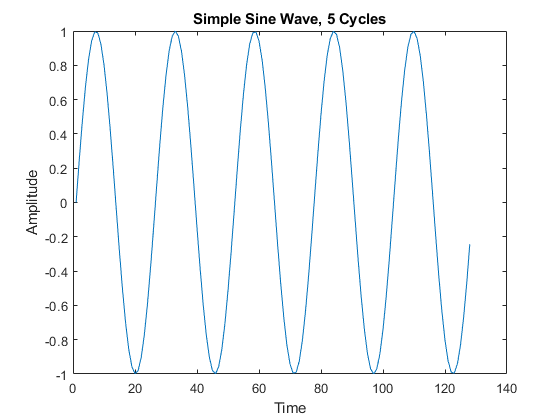

plot(y)
title ("Simple Sine Wave, 5 Cycles")
xlabel("Time")
ylabel("Amplitude")

Created `sinegen.m` and test:

y2 = sinegen(25600, 1000, 255)

y2 =          0    0.2430    0.4714    0.6716    0.8315    0.9415    0.9952    0.9892    0.9239    0.8032    0.6344    0.4276    0.1951   -0.0491   -0.2903   -0.5141   -0.7071   -0.8577   -0.9569   -0.9988   -0.9808   -0.9040   -0.7730   -0.5957   -0.3827   -0.1467    0.0980    0.3369    0.5556    0.7410    0.8819    0.9700    1.0000    0.9700    0.8819    0.7410    0.5556    0.3369    0.0980   -0.1467   -0.3827   -0.5957   -0.7730   -0.9040   -0.9808   -0.9988   -0.9569   -0.8577   -0.7071   -0.5141


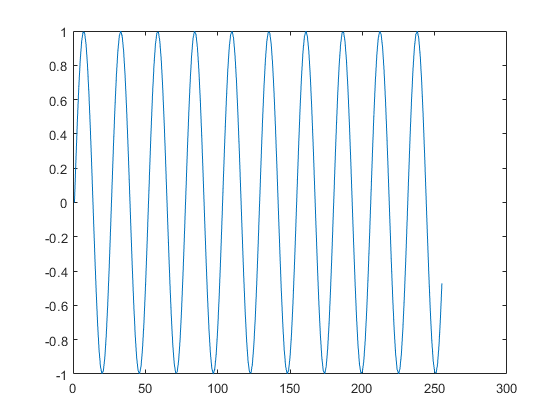

plot(y2)

Exercise 2

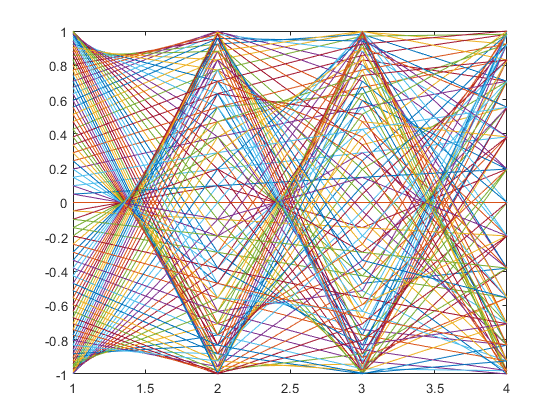

nsamp = 128;        % number of samples
S(1,:) = sinegen(fsamp, fsig,   nsamp);
S(2,:) = sinegen(fsamp, 2*fsig, nsamp);
S(3,:) = sinegen(fsamp, 3*fsig, nsamp);
S(4,:) = sinegen(fsamp, 4*fsig, nsamp);

% Is this plot correct? If not, why?
plot(S) 

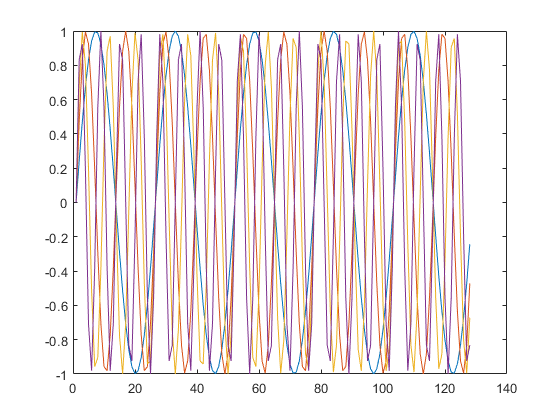

% Not required, but explain this plot too 
plot(S')


% Explain this result in lab report
for i = 1:10
    S(i,:) = sinegen(fsamp, i*fsig, nsamp);
end

S

S =          0    0.2430    0.4714    0.6716    0.8315    0.9415    0.9952    0.9892    0.9239    0.8032    0.6344    0.4276    0.1951   -0.0491   -0.2903   -0.5141   -0.7071   -0.8577   -0.9569   -0.9988   -0.9808   -0.9040   -0.7730   -0.5957   -0.3827   -0.1467    0.0980    0.3369    0.5556    0.7410    0.8819    0.9700    1.0000    0.9700    0.8819    0.7410    0.5556    0.3369    0.0980   -0.1467   -0.3827   -0.5957   -0.7730   -0.9040   -0.9808   -0.9988   -0.9569   -0.8577   -0.7071   -0.5141
         0    0.4714    0.8315    0.9952    0.9239    0.6344    0.1951   -0.2903   -0.7071   -0.9569   -0.9808   -0.7730   -0.3827    0.0980    0.5556    0.8819    1.0000    0.8819    0.5556    0.0980   -0.3827   -0.7730   -0.9808   -0.9569   -0.7071   -0.2903    0.1951    0.6344    0.9239    0.9952    0.8315    0.4714    0.0000   -0.4714   -0.8315   -0.9952   -0.9239   -0.6344   -0.1951    0.2903    0.7071    0.9569    0.9808    0.7730    0.3827   -0.0980   -0.5556   -0.8819   -1.0000   -0

p = ones(1,10)

p =      1     1     1     1     1     1     1     1     1     1


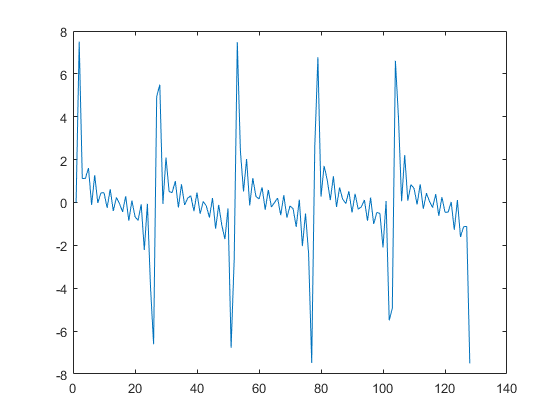

f = p*S;   % Matrix multiplacation as summation
plot(f);


%What do we get with these weights?
bn = [ 1  0  1/3  0  1/5  0  1/7  0  1/9  0 ]

bn =     1.0000         0    0.3333         0    0.2000         0    0.1429         0    0.1111         0


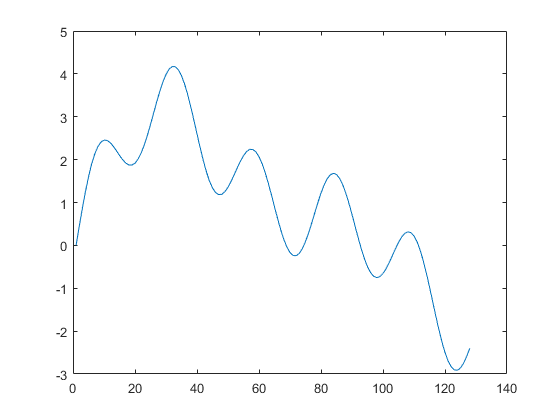

for i_bn = 1:10
    S_bn(i_bn,:) = sinegen(fsamp, bn(i_bn)*fsig, nsamp);
end

f_bn = p*S_bn;   % Matrix multiplacation as summation
plot(f_bn)


% Bn to produce saw-tooth waveform?

% Wrong
% plot(S_bn)
% Right
% plot(S_bn');

Using cosine signals as base functions:

an = [ 1  0  -1/3  0  1/5  0  -1/7  0  1/9  0 ]

an =     1.0000         0   -0.3333         0    0.2000         0   -0.1429         0    0.1111         0


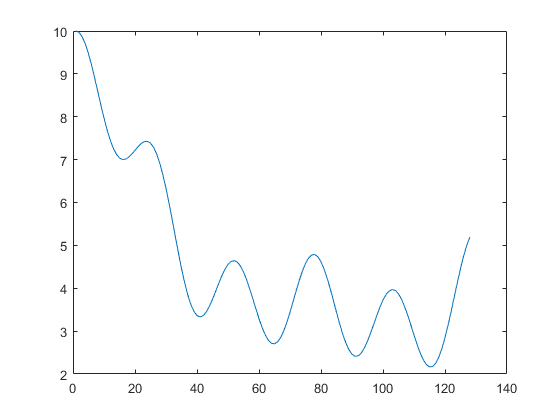

for i_an = 1:10
    C_an(i_an,:) = cosinegen(fsamp, an(i_an)*fsig, nsamp);
end

f_an = p*C_an;
plot(f_an);

Evaluating spectra of signals using DFT:

x = sinegen(8000, 1000, 8);
A = fft(x)

A =    0.0000 + 0.0000i  -0.0000 - 4.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 4.0000i


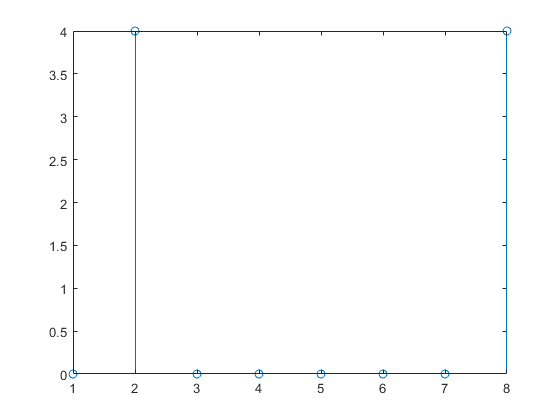

stem(abs(A))


xcos = cosinegen(8000, 1000, 8)

xcos =     1.0000    0.7071    0.0000   -0.7071   -1.0000   -0.7071   -0.0000    0.7071


Acos = fft(xcos)

Acos =   -0.0000 + 0.0000i   4.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   4.0000 + 0.0000i


stem(abs(Acos))

Spectrum for an impulse with 16 samples:

ximp(1:16) = zeros(1,16);
ximp(1) = 1

ximp =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Aximp = fft(ximp)

Aximp =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


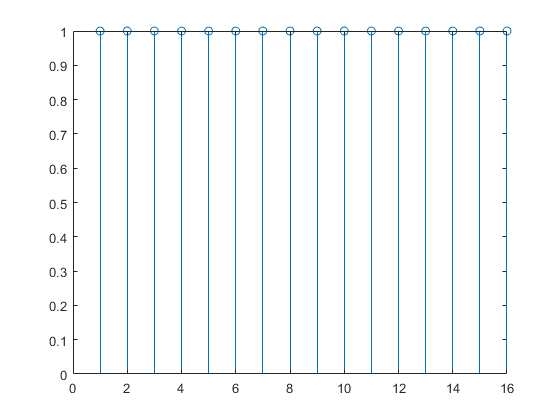

stem(abs(Aximp));


ximp2(1:16) = zeros(1,16);
ximp2(2) = 1

ximp2 =      0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Aximp2 = fft(ximp2)

Aximp2 =    1.0000 + 0.0000i   0.9239 - 0.3827i   0.7071 - 0.7071i   0.3827 - 0.9239i   0.0000 - 1.0000i  -0.3827 - 0.9239i  -0.7071 - 0.7071i  -0.9239 - 0.3827i  -1.0000 + 0.0000i  -0.9239 + 0.3827i  -0.7071 + 0.7071i  -0.3827 + 0.9239i   0.0000 + 1.0000i   0.3827 + 0.9239i   0.7071 + 0.7071i   0.9239 + 0.3827i


stem(abs(Aximp2));


ximp4(1:16) = zeros(1,16);
ximp4(4) = 1

ximp4 =      0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0


Aximp4 = fft(ximp4)

Aximp4 =    1.0000 + 0.0000i   0.3827 - 0.9239i  -0.7071 - 0.7071i  -0.9239 + 0.3827i   0.0000 + 1.0000i   0.9239 + 0.3827i   0.7071 - 0.7071i  -0.3827 - 0.9239i  -1.0000 + 0.0000i  -0.3827 + 0.9239i   0.7071 + 0.7071i   0.9239 - 0.3827i   0.0000 - 1.0000i  -0.9239 - 0.3827i  -0.7071 + 0.7071i   0.3827 + 0.9239i


stem(abs(Aximp4));

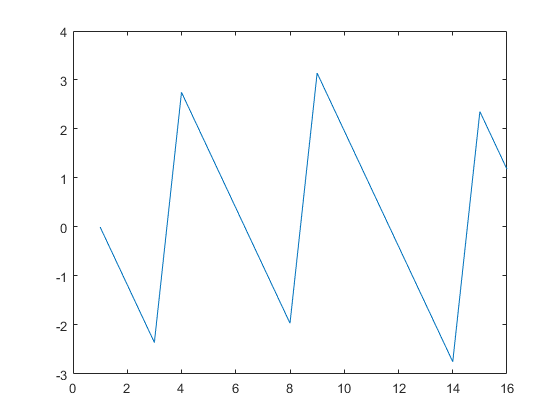


plotspec(Aximp4);